Set-up the averaging FIR filter

Fs=0.6e3;
Fnull=60; % frequency nulls and its multiple
N=Fs/Fnull

N = 10

Calculating where the nulls are:

for l=1:N/2
nulls=Fs/N*l    
end

nulls = 60

nulls = 120

nulls = 180

nulls = 240

nulls = 300

Plotting the frequency response

StartFreq=1e0;
StopFreq=Fs;
NumbPnts=1000;
FreqStep=(StopFreq-StartFreq)/(NumbPnts-1);

MagResp=zeros(NumbPnts,1);
PhasResp=zeros(NumbPnts,1);
Freq=zeros(NumbPnts,1);


for i=1:NumbPnts
    Freq(i)=StartFreq+(i-1)*FreqStep;
    H=1/N*sin(pi*Freq(i)*N/Fs)/sin(pi*Freq(i)/Fs);
    MagResp(i)=20*log10(abs(H)^2); %calculating absolute magnitude in db
    PhasResp(i)=angle(H)*360/(2*pi); %calculating phase in degree
end


Plot magnitude vs frequency

subplot(2,1,1)
HMag=semilogx(Freq/1,MagResp,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (Hz)')
ylabel('Magnitude Response (db)')
xlim([0 Fs/2]);
ylim([-100 5]);
grid on

Plot phase response

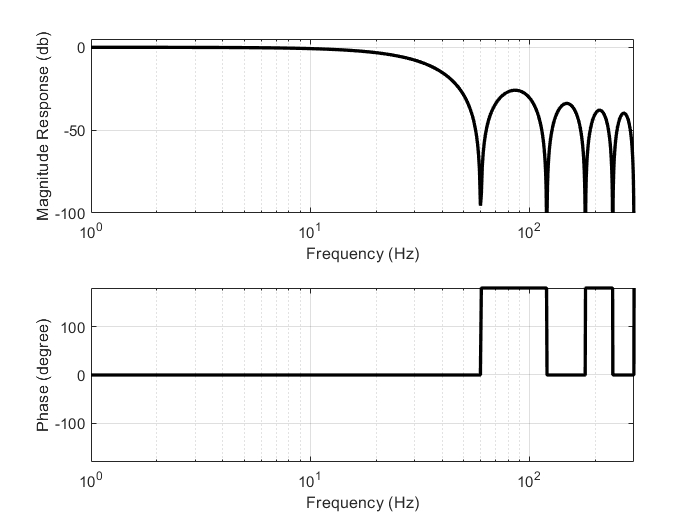

subplot(2,1,2)
HMag=semilogx(Freq/1,PhasResp,'color','k','linewidth',2);
%set(gca,'FrontSize',12);
xlabel('Frequency (Hz)')
ylabel('Phase (degree)')
xlim([0 Fs/2]);
ylim([-180 180]);
grid on